syms alpha1(t) alpha2(t) Y
syms q [2 1]
syms Lag [2 1]
syms eqns [2 1]

q(1) = alpha1;
q(2) = alpha2;
dq = diff(q,t);

m1 = 0.5;
m2 = 0.15;
l1 = 0.1;
l2 = 0.1;
g = 9.8;

% REMEBER alpha is the angle with the vertical
x1 = l1*sin(alpha1);
y1 = -l1*cos(alpha1);
x2 = l1*sin(alpha1) + l2*sin(alpha2);
y2 = -l1*cos(alpha1) - l2*cos(alpha2);

T = 0.5*(m1*((diff(x1,t))^2 + (diff(y1,t))^2) + m2*((diff(x2,t))^2 + (diff(y2,t))^2));
V = m1*g*y1 + m2*g*y2;
D = (0.01624)*((diff(x1,t))^2 + (diff(y1,t))^2) + (0.01624)*((diff(x2,t))^2 + (diff(y2,t))^2)

$$D(t) = \begin{array}{l} \frac{203\,{\cos\left(\alpha_{1}\left(t\right)\right)}^{2}\,\sigma_{1}}{1250000}+\frac{203\,{\sin\left(\alpha_{1}\left(t\right)\right)}^{2}\,\sigma_{1}}{1250000}+\frac{{\left(\frac{\cos\left(\alpha_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{1}\left(t\right)}{10}+\frac{\cos\left(\alpha_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{2}\left(t\right)}{10}\right)}^{2}\,203}{12500}+\frac{{\left(\frac{\sin\left(\alpha_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{1}\left(t\right)}{10}+\frac{\sin\left(\alpha_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\alpha_{2}\left(t\right)}{10}\right)}^{2}\,203}{12500}\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}\alpha_{1}\left(t\right)\right)}^{2} \end{array}$$

L = T-V;

for i=1:2
    Lag(i) = diff(diff(L,dq(i)),t) - diff(L,q(i)) + diff(D,dq(i)) == 0;
end
for i=1:2
    eqns(i) = simplify(lhs(Lag(i)) - rhs(Lag(i)), 'Steps', 100);
end
eqns == 0 %#ok<EQEFF> 

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{637\,\sin\left(\alpha_{1}\left(t\right)\right)}{1000}+\frac{3\,\sin\left(\sigma_{1}\right)\,{\left(\frac{\partial }{\partial t}\alpha_{2}\left(t\right)\right)}^{2}}{2000}+\frac{3\,\cos\left(\sigma_{1}\right)\,\sigma_{2}}{2000}+\frac{203\,\frac{\partial }{\partial t}\alpha_{1}\left(t\right)}{312500}+\frac{203\,\cos\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}\alpha_{2}\left(t\right)}{625000}+\frac{13\,\sigma_{3}}{2000}=0\\ \frac{147\,\sin\left(\alpha_{2}\left(t\right)\right)}{1000}-\frac{3\,\sin\left(\sigma_{1}\right)\,{\left(\frac{\partial }{\partial t}\alpha_{1}\left(t\right)\right)}^{2}}{2000}+\frac{3\,\cos\left(\sigma_{1}\right)\,\sigma_{3}}{2000}+\frac{203\,\frac{\partial }{\partial t}\alpha_{2}\left(t\right)}{625000}+\frac{203\,\cos\left(\sigma_{1}\right)\,\frac{\partial }{\partial t}\alpha_{1}\left(t\right)}{625000}+\frac{3\,\sigma_{2}}{2000}=0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\alpha_{1}\left(t\right)-\alpha_{2}\left(t\right)\\ \sigma_{2}=\frac{\partial^{2}}{\partial t^{2}}\alpha_{2}\left(t\right)\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}\alpha_{1}\left(t\right) \end{array}$$

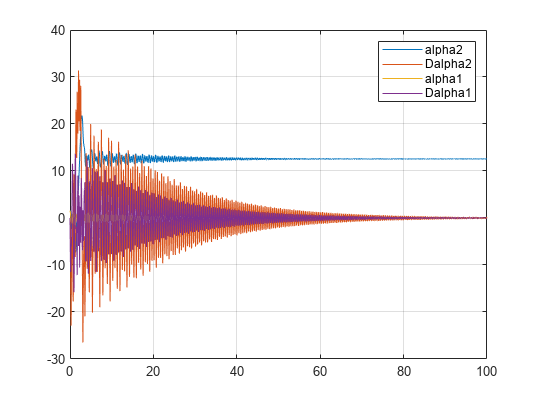


[VF,Subs] = odeToVectorField(Lag);
odefcn = matlabFunction(VF, 'Vars',{t,Y});
[X,Y] = ode45(odefcn, [0 100], [pi/2 0 pi/2 0]);

plot(X, Y)
grid
legend(string(Subs))

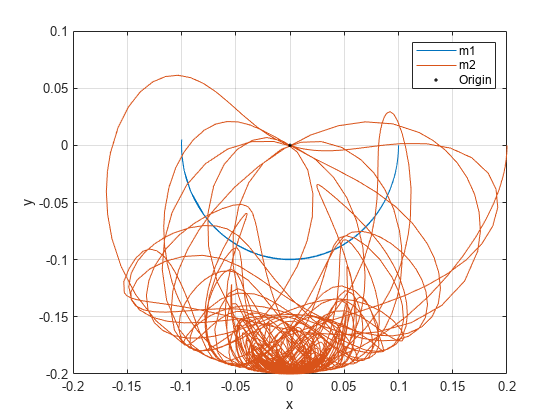


X1 = l1*sin(Y(:,3));
Y1 = -l1*cos(Y(:,3));
X2 = l1*sin(Y(:,3)) + l2*sin(Y(:,1));
Y2 = -l1*cos(Y(:,3)) - l2*cos(Y(:,1));

plot(X1,Y1,'DisplayName','m1')
grid
hold on
plot(X2,Y2,'DisplayName','m2')
legend
xlabel('x')
ylabel('y')
plot(0,0,'.k','DisplayName','Origin')
hold off

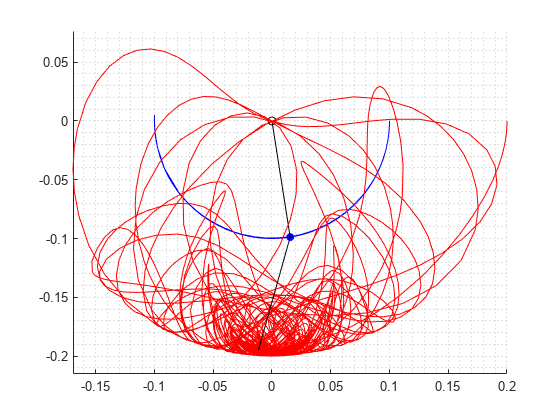

%{
%ANIMATION
figure
hold on
grid minor 
axis equal
% Plotting with no color to set axis limits
plot(X1,Y1,'Color','none');
plot(X2,Y2,'Color','none');
% Plotting the first iteration
plot(0,0,'ko')
p1 = plot(X1(1),Y1(1),'b');
m1 = scatter(X1(1),Y1(1),'filled','b');
l1 = plot([0 X1(1)],[0 Y1(1)],'k-');
p2 = plot(X2(1),Y2(1),'r');
m2 = scatter(X2(1),Y2(1),'filled','r');
l2 = plot([X1(1) X2(1)],[Y1(1) Y2(1)],'k-');

% Iterating through the length of the time array
for k = 1:length(Y(:,1))
    % Updating the line
    p1.XData = X1(1:k);
    p1.YData = Y1(1:k);
    p2.XData = X2(1:k);
    p2.YData = Y2(1:k);
    % Updating the point
    m1.XData = X1(k); 
    m1.YData = Y1(k);
    m2.XData = X2(k); 
    m2.YData = Y2(k);
    l1.XData = [0 X1(k)];
    l1.YData = [0 Y1(k)];
    l2.XData = [X1(k) X2(k)];
    l2.YData = [Y1(k) Y2(k)];
    % Delay
    pause(0.05)
end
%}
